## Introduction

A testbed was developed to spectrally reproduce display stimuli for testing color calibration kits. The testbed, LightSim, consists of a tunable light source (TLS) for generating the target spectrum, an integrating sphere for diffusing the light for the color calibration sensor, computer hardware and software components for controlling the TLS, and a spectroradiometer for measuring the output spectrum. 

The testbed was treated as a 1-pixel, 1024-primary, 40,000-level display in contrast to the regular n-pixel, 3-primary, 256-level displays. The TLS used 1024 columns of a digital light processor (DLP) to selectively reflect the dispersed light coming from a xenon lamp after passing the grating. Each column was independently controlled by an integer value between 0 and 40,000 to form a bandpass filter with a bandwidth of 25 nm at a spectral resolution of 0.40 nm. The spectroradiometer measured the output spectrum between 380 nm and 780 nm at 1 nm resolution.

The final forward model accepts a vector of 1024 column values and predicts the output spectrum of 401 wavelengths.

To simulate the stimuli of a given display, the TLS model needed to be inversed by solving the 1024x401 matrix equation with the R General Purpose Optimization tool (optim L-BFGS-B). The inverse model accepts a target spectrum and then calculates the 1024 column values.

## Setup

Controlling OL490/HIMS1 and PR730 in WO62/3143

ol

ol =   OL490Class with properties:

                   m: [1×1 OL490_SDK_Dll.OL490SdkLibrary]
            asmCyUSB: []
        asmOLIPlugin: []
         asmOL490Lib: []
         asmOL490SDK: []
    max_column_value: 40000
           gamma_lut: [11×2 double]
           classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@OL490Class'
               vec_x: [1024×1 double]
               vec_y: [1024×1 double]
               vec_z: [1024×1 double]
                HIMS: 1


cs

cs =   cs2000Class with properties:

         ver: '6/28/2022'
     comPort: [1×1 rs232ClassCS2000]
    settings: 'CS2000'


ols = OL490Sim

ols =   OL490Sim with properties:

             col_spec: []
             HIMS_VER: 'HIMS2_07032022'
       spike_filename: 'spike_HIMS2_07032022.mat'
       gamma_filename: 'gamma_HIMS2_07032022.mat'
    col_spec_filename: 'col_spec_HIMS2_07032022.mat'
             speC_max: []
             speC_min: []
            reflC_min: []
            classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@OL490Sim'
        spikedatapath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@OL490Sim/spike_HIMS2_07032022.mat'
     col_specdatapath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@OL490Sim/col_spec_HIMS2_07032022.mat'
        gammadatapath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@OL490Sim/gamma_HIMS2_07032022.mat'


## Collect gamma measurement data

Measure 0%, 10%,... 100% of the fully on output spectrum.

Use the area under the curve (i.e., total power, which should be proportional to luminance) to determine gamma.

In the characterization stage, 350 out of 1024 columns were measured to construct the look-up table of the spectral reflectance. To avoid the prolonged measurement time required by the spectroradiometer to collect a limited number of photons reflected by one column only, seven columns were activated simultaneously to generate eight spikes that were at least 50 nm apart without any cross-talking.

ols.FWD_stimulate_gamma (ol,cs)

time_gamma = uint64
1762286591229

Gamma measurement: 1 of 11


Yxy =     0.0208    0.4069    0.4141


Gamma measurement: 2 of 11


Yxy =     0.0313    0.3799    0.3946


Gamma measurement: 3 of 11


Yxy =     0.0550    0.3458    0.3698


Gamma measurement: 4 of 11


Yxy =     0.2532    0.3693    0.3926


Gamma measurement: 5 of 11


Yxy =     0.7498    0.3582    0.3934


Gamma measurement: 6 of 11


Yxy =     2.3152    0.3732    0.4034


Gamma measurement: 7 of 11


Yxy =     4.7002    0.3675    0.4016


Gamma measurement: 8 of 11


Yxy =     8.5005    0.3709    0.4041


Gamma measurement: 9 of 11


Yxy =    14.8130    0.3757    0.4066


Gamma measurement: 10 of 11


Yxy =    23.4380    0.3787    0.4080


Gamma measurement: 11 of 11


Yxy =    33.2280    0.3802    0.4082


time_spent = 803.8196

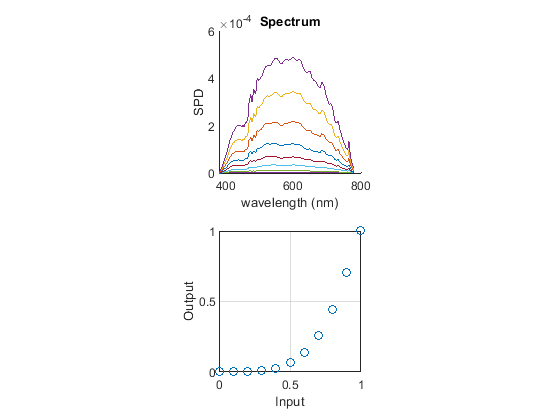

ols.FWD_stimulate_gamma_finding

## Collect spectral measurement data

ols.FWD_stimulate_spectrally (ol,cs)

time_spectrally = uint64
125439766537

Spectral measurement: 1 of 50


Yxy =    36.5600    0.3796    0.4081


Yxy =     0.3092    0.3879    0.4090


Spectral measurement: 2 of 50


Yxy =    36.7950    0.3796    0.4082


Yxy =     0.3094    0.3885    0.4097


Spectral measurement: 3 of 50


Yxy =    36.5970    0.3797    0.4082


Yxy =     0.3092    0.3889    0.4100


Spectral measurement: 4 of 50


Yxy =    36.2800    0.3797    0.4082


Yxy =     0.3091    0.3893    0.4105


Spectral measurement: 5 of 50


Yxy =    36.4480    0.3795    0.4081


Yxy =     0.3080    0.3895    0.4104


Spectral measurement: 6 of 50


Yxy =    36.4720    0.3796    0.4081


Yxy =     0.3076    0.3895    0.4108


Spectral measurement: 7 of 50


Yxy =    36.6580    0.3795    0.4081


Yxy =     0.3071    0.3902    0.4105


Spectral measurement: 8 of 50


Yxy =    36.6840    0.3796    0.4081


Yxy =     0.3075    0.3895    0.4116


Spectral measurement: 9 of 50


Yxy =    36.6460    0.3796    0.4081


Yxy =     0.3066    0.3900    0.4111


Spectral measurement: 10 of 50


Yxy =    36.5940    0.3796    0.4081


Yxy =     0.3074    0.3888    0.4125


Spectral measurement: 11 of 50


Yxy =    36.7400    0.3796    0.4082


Yxy =     0.3072    0.3890    0.4115


Spectral measurement: 12 of 50


Yxy =    36.5620    0.3795    0.4081


Yxy =     0.3068    0.3875    0.4127


Spectral measurement: 13 of 50


Yxy =    36.6130    0.3796    0.4082


Yxy =     0.3068    0.3872    0.4116


Spectral measurement: 14 of 50


Yxy =    36.5210    0.3796    0.4081


Yxy =     0.3073    0.3859    0.4110


Spectral measurement: 15 of 50


Yxy =    36.5820    0.3794    0.4079


Yxy =     0.3078    0.3851    0.4111


Spectral measurement: 16 of 50


Yxy =    36.7630    0.3795    0.4081


Yxy =     0.3081    0.3838    0.4107


Spectral measurement: 17 of 50


Yxy =    36.4890    0.3796    0.4081


Yxy =     0.3084    0.3828    0.4101


Spectral measurement: 18 of 50


Yxy =    36.9070    0.3795    0.4081


Yxy =     0.3087    0.3819    0.4110


Spectral measurement: 19 of 50


Yxy =    36.7260    0.3795    0.4081


Yxy =     0.3091    0.3819    0.4096


Spectral measurement: 20 of 50


Yxy =    36.4760    0.3796    0.4081


Yxy =     0.3094    0.3802    0.4105


Spectral measurement: 21 of 50


Yxy =    37.0950    0.3795    0.4081


Yxy =     0.3090    0.3804    0.4098


Spectral measurement: 22 of 50


Yxy =    36.7140    0.3797    0.4082


Yxy =     0.3103    0.3787    0.4109


Spectral measurement: 23 of 50


Yxy =    36.6990    0.3795    0.4081


Yxy =     0.3102    0.3791    0.4103


Spectral measurement: 24 of 50


Yxy =    36.4760    0.3796    0.4080


Yxy =     0.3102    0.3782    0.4098


Spectral measurement: 25 of 50


Yxy =    36.4950    0.3795    0.4081


Yxy =     0.3105    0.3768    0.4085


Spectral measurement: 26 of 50


Yxy = 1×3
   36.7540    0.3795    0.4081


Yxy = 1×3
    0.3109    0.3761    0.4085


Spectral measurement: 27 of 50


Yxy = 1×3
   36.4770    0.3796    0.4081


Yxy = 1×3
    0.3122    0.3750    0.4073


Spectral measurement: 28 of 50


Yxy = 1×3
   36.5260    0.3795    0.4080


Yxy = 1×3
    0.3114    0.3742    0.4065


Spectral measurement: 29 of 50


Yxy = 1×3
   36.7470    0.3795    0.4081


Yxy = 1×3
    0.3125    0.3741    0.4045


Spectral measurement: 30 of 50


Yxy = 1×3
   36.6970    0.3794    0.4081


Yxy = 1×3
    0.3115    0.3726    0.4043


Spectral measurement: 31 of 50


Yxy = 1×3
   36.5360    0.3796    0.4082


Yxy = 1×3
    0.3127    0.3729    0.4030


Spectral measurement: 32 of 50


Yxy = 1×3
   36.6010    0.3797    0.4081


Yxy = 1×3
    0.3124    0.3722    0.4031


Spectral measurement: 33 of 50


Yxy = 1×3
   36.5880    0.3795    0.4081


Yxy = 1×3
    0.3119    0.3735    0.4028


Spectral measurement: 34 of 50


Yxy = 1×3
   36.4300    0.3796    0.4081


Yxy = 1×3
    0.3115    0.3730    0.4035


Spectral measurement: 35 of 50


Yxy = 1×3
   36.4960    0.3796    0.4081


Yxy = 1×3
    0.3115    0.3744    0.4030


Spectral measurement: 36 of 50


Yxy = 1×3
   36.5030    0.3796    0.4081


Yxy = 1×3
    0.3114    0.3752    0.4031


Spectral measurement: 37 of 50


Yxy = 1×3
   36.8050    0.3796    0.4081


Yxy = 1×3
    0.3118    0.3756    0.4035


Spectral measurement: 38 of 50


Yxy = 1×3
   36.3090    0.3795    0.4080


Yxy = 1×3
    0.3114    0.3764    0.4038


Spectral measurement: 39 of 50


Yxy = 1×3
   36.5340    0.3796    0.4082


Yxy = 1×3
    0.3113    0.3767    0.4036


Spectral measurement: 40 of 50


Yxy = 1×3
   36.6320    0.3795    0.4080


Yxy = 1×3
    0.3114    0.3777    0.4041


Spectral measurement: 41 of 50


Yxy = 1×3
   36.6590    0.3795    0.4081


Yxy = 1×3
    0.3108    0.3780    0.4040


Spectral measurement: 42 of 50


Yxy = 1×3
   36.6520    0.3795    0.4081


Yxy = 1×3
    0.3113    0.3793    0.4048


Spectral measurement: 43 of 50


Yxy = 1×3
   36.6740    0.3795    0.4081


Yxy = 1×3
    0.3114    0.3804    0.4041


Spectral measurement: 44 of 50


Yxy = 1×3
   36.8870    0.3795    0.4081


Yxy = 1×3
    0.3126    0.3813    0.4046


Spectral measurement: 45 of 50


Yxy = 1×3
   36.8190    0.3795    0.4081


Yxy = 1×3
    0.3127    0.3828    0.4055


Spectral measurement: 46 of 50


Yxy = 1×3
   37.0530    0.3793    0.4080


Yxy = 1×3
    0.3118    0.3833    0.4059


Spectral measurement: 47 of 50


Yxy = 1×3
   36.8300    0.3794    0.4080


Yxy = 1×3
    0.3118    0.3847    0.4065


Spectral measurement: 48 of 50


Yxy = 1×3
   36.7920    0.3796    0.4082


Yxy = 1×3
    0.3111    0.3855    0.4071


Spectral measurement: 49 of 50


Yxy = 1×3
   36.9670    0.3795    0.4081


Yxy = 1×3
    0.3109    0.3865    0.4081


Spectral measurement: 50 of 50


Yxy = 1×3
   36.6780    0.3795    0.4081


Yxy = 1×3
    0.3104    0.3873    0.4088


Yxy = 1×3
    0.0232    0.4063    0.4138


time_spent = 1.3617e+03

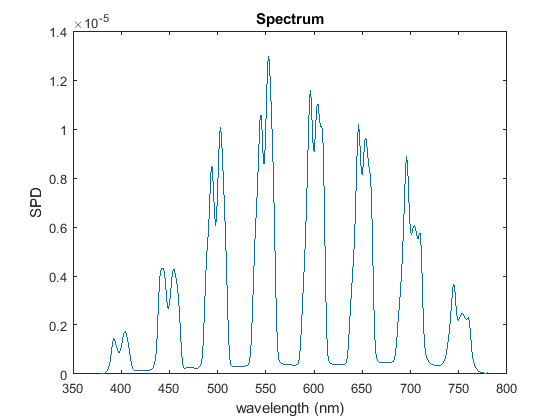

ols.FWD_stimulate_spectrally_finding

## Analyze spectral measurement data

ols.FWD_characterize_spectrally

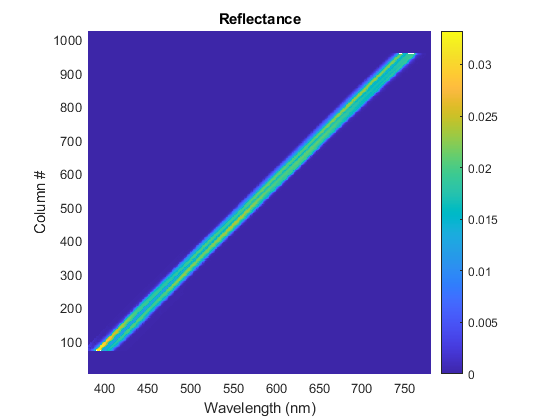


ols.FWD_characterize_spectrally_finding

## Check accuracy of the forward model

Column 1000 is not modeled because 780 nm is excluded in the combs.

col_range  = [100:100:1000];

vec = OL490Class.VEC_multiple_peaks(col_range);

refl = ols.FWD_vec2reflC(vec);
spec = ols.FWD_vec2spdC(vec);

clf
hold on
spec.plot

mea = ol.setColumn1024GammaandMeasure(vec,cs);

Yxy =     0.3838    0.3847    0.4136


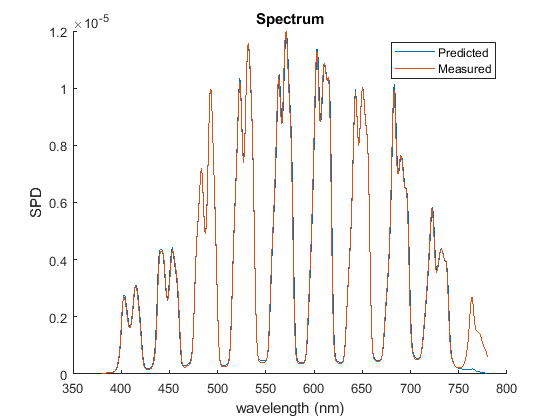

mea.plot

legend('Predicted','Measured')

## Check accuracy of the inverse model with 3 displays

Spectra of the red, green, and blue primaries of three displays were used to represent different color gamuts and lighting methods. A virtual reality device based on OLED (Oculus Rift), a professional-grade display based on CCFL-backlighting (NEC PA271), and a consumer-grade display based on LED-backlighting (HP Z24X) were measured to represent the DCI-P3, AdobeRGB, and sRGB color spaces. For each display, a model was created to accept the RGB input values and then predict the output spectrum.

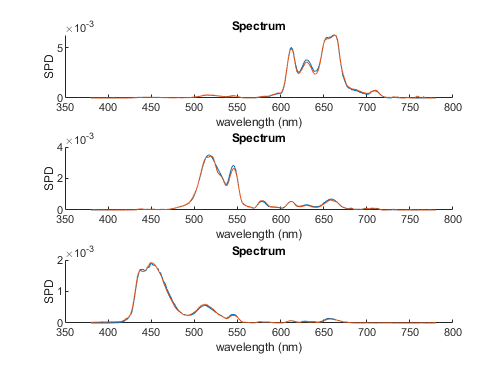

### NEC

disp = NECPA271Sim

disp =   NECPA271Sim with properties:

            sc: 1
        spec_r: [1×401 double]
        spec_g: [1×401 double]
        spec_b: [1×401 double]
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@NECPA271Sim'
    gamma_srgb: []
         vec_r: [1024×1 double]
         vec_g: [1024×1 double]
         vec_b: [1024×1 double]


Yxy =     1.7747    0.6914    0.3060


Yxy =     2.3107    0.1604    0.7446


Yxy =     0.1505    0.1569    0.0265


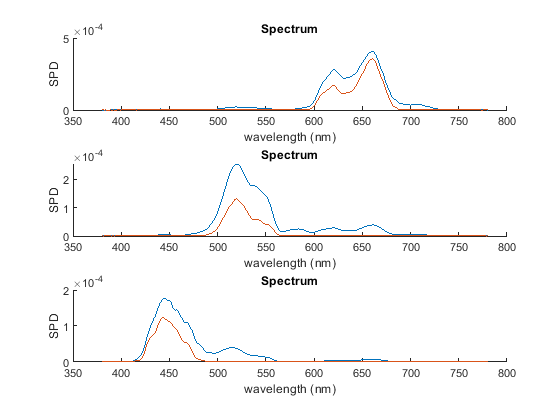

compare_RGB_primaries(ol,ols,cs,disp)

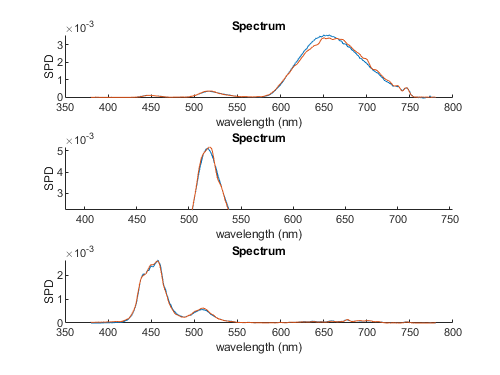

### HP

disp = HPZ24xSim
compare_RGB_primaries(ol,ols,cs,disp)

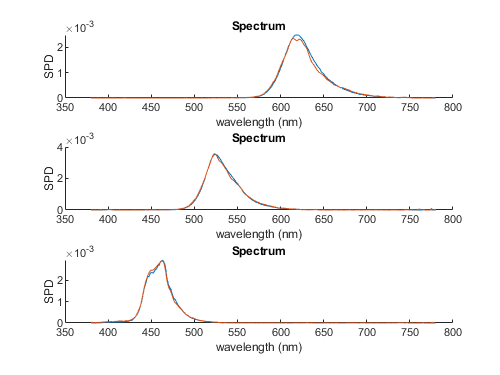

### Rift

disp = RiftSim
compare_RGB_primaries(ol,ols,cs,disp)

## ColorChecker Experiments

In the experiment, a color calibration sensor (DataColor Spyder X Elite) was tested with the 24 patches following the ColorChecker design. Each spectrum was simultaneously measured by the spectroradiometer (Konica-Minolta CS2000a) as the ground truth. The subject sensor allowed the user to select one of four backlighting modes (“White LED”, “Standard LED”, “General”, and “GB LED”) for improving the estimation. The test results were evaluated using the CIEDE2000 color difference metric. The experiment results show adequate linearity of luminance responses in the mid-range. Most color differences were less than 2.5 ΔE00, except for the darkest patch #24, indicating the limited capability of measuring dark shades. None of the four backlighting modes outperformed the others, and two blue patches #8 and #13 generated the most diverse results. This exercise demonstrated the utility of the LightSim for emulating arbitrary spectra without employing actual displays based on different backlighting methods.

## Try to match CMF

#### Modeling

sc = 0.001;
cmf_x = interp1(cc.cmf(:,1),cc.cmf(:,2),380:780)';
cmf_y = interp1(cc.cmf(:,1),cc.cmf(:,3),380:780)';
cmf_z = interp1(cc.cmf(:,1),cc.cmf(:,4),380:780)';

vec_x = ols.INV_spd2vec(cmf_x*sc);
vec_y = ols.INV_spd2vec(cmf_y*sc);
vec_z = ols.INV_spd2vec(cmf_z*sc);

save('vec_colormatchingfunction','vec_x','vec_y','vec_z','cmf_x','cmf_y','cmf_z','sc')

#### Verify the vec results

load('vec_colormatchingfunction','vec_x','vec_y','vec_z','cmf_x','cmf_y','cmf_z','sc')

mea_x = ol.setColumn1024GammaandMeasure(vec_x,cs);
mea_y = ol.setColumn1024GammaandMeasure(vec_y,cs);
mea_z = ol.setColumn1024GammaandMeasure(vec_z,cs);

clf
hold on
% mea_x.plot
% mea_y.plot
% mea_z.plot

plot(380:780,cmf_x*sc,'-r')
plot(380:780,cmf_y*sc,'-g')
plot(380:780,cmf_z*sc,'-b')

plot(380:780,mea_x.amplitude,':r')
plot(380:780,mea_y.amplitude,':g')
plot(380:780,mea_z.amplitude,':b')

axis([380 780 0 2e-3])
xlabel('Wavelength (nm)')
ylabel('Power')
legend('x','y','z','x measured','y measured','z measured')

#### Wrong idea!

xy = cc.xy_srgb(2,:)
xyz = [xy 1-sum(xy)]
XYZ = xyz

XYZ = [1 0 0 ]
v = ol.XYZ2vec(XYZ);
mea = ol.setColumn1024GammaandMeasure(v,cs);
clf
mea.plot
mea.xyz

Try CIE D65

d65 = SpectrumClass.CIE_D(5000);
target_orig = d65.amplitude;

sc = 0.00002;
clf
hold on
ols.speC_max.plot
plot(380:780,target_orig*sc)

target = target_orig * sc;
vec = ols.INV_spd2vec(target);
vec_d50 = vec;

mea = ol.setColumn1024GammaandMeasure(vec,cs);
clf
hold on
plot(380:780,target)
mea.plot
mea.xyz

function compare_RGB_primaries (ol,ols,cs,disp)

clf

subplot(3,1,1)
hold on
v = disp.vec_r;
s_predicted = ols.FWD_vec2spdC(v);
mea = ol.setColumn1024GammaandMeasure(v,cs);
s_predicted.plot
mea.plot

subplot(3,1,2)
hold on
v = disp.vec_g;
s_predicted = ols.FWD_vec2spdC(v);
mea = ol.setColumn1024GammaandMeasure(v,cs);
s_predicted.plot
mea.plot

subplot(3,1,3)
hold on
v = disp.vec_b;
s_predicted = ols.FWD_vec2spdC(v);
mea = ol.setColumn1024GammaandMeasure(v,cs);
s_predicted.plot
mea.plot
end